# Taller 1 — Control robusto H-inf en UAV

**Teoria de Control Digital — Universidad Nacional de Colombia**

Autores: [Nombres de los integrantes]

Fecha: Mayo 2026

## 1. Objetivo

Disenar y comparar dos estrategias de control para el seguimiento de actitud (pitch $\theta$ y roll $\phi$) de un UAV linealizado:

- **SAS/CAS** — Control clasico con PI de angulo + amortiguamiento por velocidad angular (root locus).

- **H-inf por sensibilidad mixta** — Control robusto SISO usando `mixsyn` con pesos $W_1$, $W_2$ y $W_3$.

## 2. Especificaciones de diseno

Las especificaciones vienen del enunciado del taller:

- Referencia maxima: 40 deg

- Limite de actuador: $\pm 30$ deg

- Ancho de banda del actuador: 8 Hz ($\omega_b = 2\pi \cdot 8$ rad/s)

- Frecuencia de perturbacion: 6 Hz ($\omega_p = 2\pi \cdot 6$ rad/s)

- Ruido de medicion longitudinal: $10^{-4}$ rad$^2$

- Ruido de medicion lateral: $10^{-3}$ rad$^2$

**Funciones de sensibilidad y sus relaciones con las especificaciones:**


$$S(s) = \frac{1}{1+G(s)K(s)}, \quad T(s) = \frac{G(s)K(s)}{1+G(s)K(s)}, \quad K(s)S(s)$$


- $|S(j\omega)| < |1/W_1(j\omega)|$ — seguimiento en baja frecuencia

- $|K(j\omega)S(j\omega)| < |1/W_2(j\omega)|$ — esfuerzo de control

- $|T(j\omega)| < |1/W_3(j\omega)|$ — rechazo de ruido en alta frecuencia

## 3. Modelo del UAV

El modelo lineal se entrego como `modelo_lin.mat` con tres objetos:

- `linmodel` — modelo completo (13 estados, 8 entradas, 14 salidas)

- `longmod` — modelo longitudinal desacoplado

- `latmod` — modelo lateral desacoplado

project_dir = fileparts(mfilename('fullpath'));
repo_dir    = fileparts(project_dir);
figures_dir = fullfile(project_dir, 'figures');

model_path = fullfile(repo_dir, 'drive', 'TDC', '02. TAREAS', ...
    'T1', 'modelo_lin.mat');
data = load(model_path);

plant_full = ss(data.linmodel);
plant_lat  = ss(data.latmod);
plant_long = ss(data.longmod);

full_inputs  = {'throttle','elevator','rudder','l_aileron','r_aileron', ...
    'l_flap','r_flap','aileron'};
full_outputs = {'V','beta','alpha','h','phi','theta','psi','p','q','r', ...
    'gamma','ax','ay','az'};
plant_full.InputName  = full_inputs;
plant_full.OutputName = full_outputs;

fprintf('Modelo completo: %d estados, %d entradas, %d salidas\n', ...
    order(plant_full), size(plant_full,2), size(plant_full,1));

Modelo completo: 13 estados, 8 entradas, 14 salidas


**Tabla de entradas y salidas:**

**Valores singulares de la planta:**

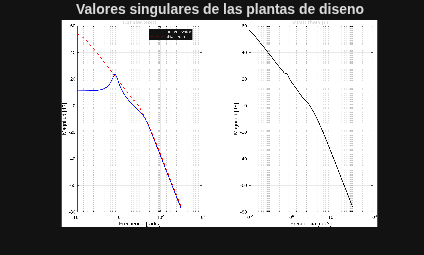

if exist(fullfile(figures_dir, 'planta_sigma.png'), 'file')
    imshow(fullfile(figures_dir, 'planta_sigma.png'));
    title('Valores singulares de las plantas de diseno');
end

## 4. Diseno SAS (Stability Augmentation System)

El SAS amortigua los modos internos de velocidad angular realimentando $q$ (pitch rate) y $p$ (roll rate) con ganancias proporcionales:


$$u_e = u_{CAS} - D_q \cdot q, \quad u_a = u_{CAS} - D_p \cdot p$$


Las ganancias se seleccionan por **root locus** sobre los canales $q/\mathrm{elevator}$ y $p/\mathrm{aileron}$:

- $D_q = -0.20$ — amortigua el modo de pitch rate

- $D_p = +0.05$ — conserva estabilidad del lazo interno de roll

- Yaw damper: $D_r = -0.065$ con filtro washout $s/(s+2)$

**Root locus SAS:**

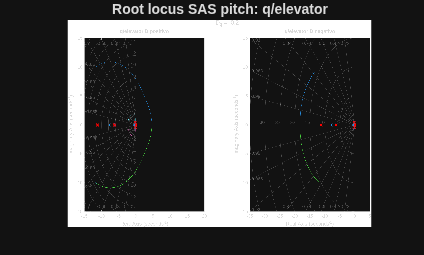

if exist(fullfile(figures_dir, 'root_locus_sas_q.png'), 'file')
    imshow(fullfile(figures_dir, 'root_locus_sas_q.png'));
    title('Root locus SAS pitch: q/elevator');
end

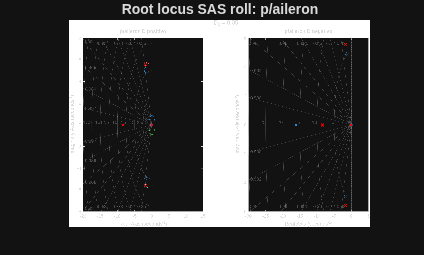

if exist(fullfile(figures_dir, 'root_locus_sas_p.png'), 'file')
    imshow(fullfile(figures_dir, 'root_locus_sas_p.png'));
    title('Root locus SAS roll: p/aileron');
end

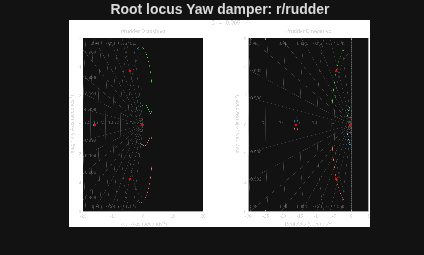

if exist(fullfile(figures_dir, 'root_locus_sas_r.png'), 'file')
    imshow(fullfile(figures_dir, 'root_locus_sas_r.png'));
    title('Root locus Yaw damper: r/rudder');
end

## 5. Diseno CAS (Control Augmentation System)

El CAS agrega tracking sobre la planta ya amortiguada por SAS. Se implementa como PI sobre el error de angulo:


$$C_{PI}(s) = K_p + \frac{K_i}{s}$$


La planta externa del CAS es:


$$G_{ext}(s) = \frac{G_\theta(s)}{1 + D_q \cdot G_q(s)}$$


**Ganancias seleccionadas:**

- Theta: $K_p = -1.00$, $K_i = -0.30$

- Phi: $K_p = -0.35$, $K_i = -0.18$

**Root locus CAS:**

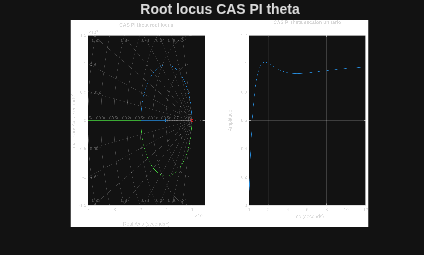

if exist(fullfile(figures_dir, 'root_locus_cas_theta.png'), 'file')
    imshow(fullfile(figures_dir, 'root_locus_cas_theta.png'));
    title('Root locus CAS PI theta');
end

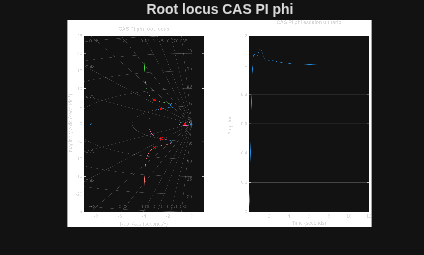

if exist(fullfile(figures_dir, 'root_locus_cas_phi.png'), 'file')
    imshow(fullfile(figures_dir, 'root_locus_cas_phi.png'));
    title('Root locus CAS PI phi');
end

## 6. Controlador PI+D equivalente

La combinacion SAS+CAS se puede ver como un controlador PI+D:


$$K(s) = K_p + \frac{K_i}{s} + \frac{K_d \cdot s}{\tau s + 1}$$


donde el termino derivativo filtrado ($\tau = 0.03$ s) corresponde al SAS por velocidad angular. El anti-windup se implementa con ganancia $K_{aw} = 8.0$ sobre la diferencia entre control crudo y saturado.

## 7. Diseno H-inf por sensibilidad mixta

**7.1 Marco teorico:**

La planta generalizada para sensibilidad mixta es:


$$P = \begin{bmatrix} W_1 & W_1 G \\ 0 & W_2 \\ -I & -G \end{bmatrix}$$


El problema H-inf busca $K$ que minimice:


$$\gamma = \left\| \begin{bmatrix} W_1 S \\ W_2 K S \\ W_3 T \end{bmatrix} \right\|_\infty$$


**7.2 Pesos $W_1$, $W_2$, $W_3$:**

**Theta:**

**Phi (iteracion ajustada para no saturar a 30 deg):**

Justificacion:

- $w_p = 2\pi \cdot 6$ rad/s aparece porque el enunciado especifica perturbaciones hasta 6 Hz; MATLAB usa rad/s en modelos continuos.

- $W_1$ grande a baja frecuencia fuerza $S$ pequeno (buen seguimiento)

- $W1_\phi = 220$ refuerza seguimiento lateral frente a la version base

- $W_2$ penaliza esfuerzo de control para evitar saturacion

- En theta, $W_2 = 5$ reduce los picos de elevator frente a la version anterior con $W_2 = 1$

- En phi, $W_2$ crece de 4 a 12: permite esfuerzo de baja frecuencia, pero castiga mas el control rapido de aileron

- El factor $12/4$ fija la separacion entre la ganancia alta y baja

- $W_3$ grande a alta frecuencia fuerza $T$ pequeno (rechazo de ruido)

Estos numeros no son una derivacion cerrada del enunciado. Vienen de los barridos documentados en la bitacora y en los reportes de resultados. La version final prioriza una restriccion fisica: H-inf no debe saturar para referencias de 30 deg, aunque eso haga el seguimiento menos agresivo.

**7.3 Resultados de la sintesis:**

## 8. Analisis de sensibilidades

**Tabla de normas H-inf:**

**Sensibilidades por eje:**

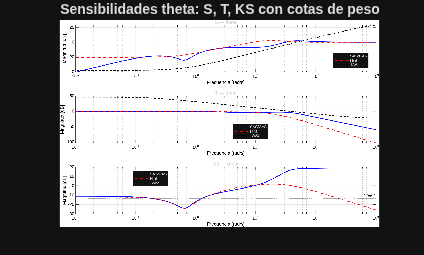

if exist(fullfile(figures_dir, 'sensibilidades_theta.png'), 'file')
    imshow(fullfile(figures_dir, 'sensibilidades_theta.png'));
    title('Sensibilidades theta: S, T, KS con cotas de peso');
end

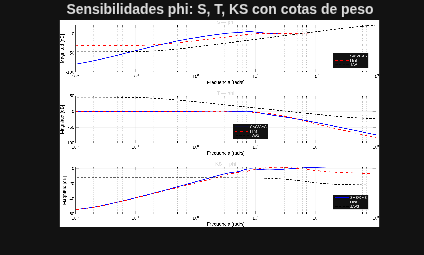

if exist(fullfile(figures_dir, 'sensibilidades_phi.png'), 'file')
    imshow(fullfile(figures_dir, 'sensibilidades_phi.png'));
    title('Sensibilidades phi: S, T, KS con cotas de peso');
end

**Cotas inversas de los pesos:**

La figura siguiente pone $1/W_1$, $1/W_2$ y $1/W_3$ en la misma grafica por eje. Esas curvas se leen como limites deseados:

- $1/W_1$ limita $S$: mientras mas baja sea la curva, mas exigente es el seguimiento/rechazo de perturbaciones a esa frecuencia.

- $1/W_2$ limita $KS$: mientras mas baja sea, menos esfuerzo de actuador se permite. Por eso subir $W_2$ fue la correccion clave contra saturacion.

- $1/W_3$ limita $T$: baja a alta frecuencia implica menor paso de ruido de medicion y dinamicas no modeladas hacia la salida.

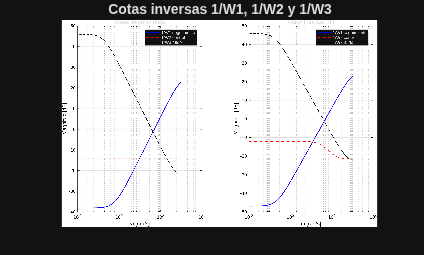

if exist(fullfile(figures_dir, 'pesos_inversos_hinf.png'), 'file')
    imshow(fullfile(figures_dir, 'pesos_inversos_hinf.png'));
    title('Cotas inversas 1/W1, 1/W2 y 1/W3');
end

**Comparacion 3x2:**

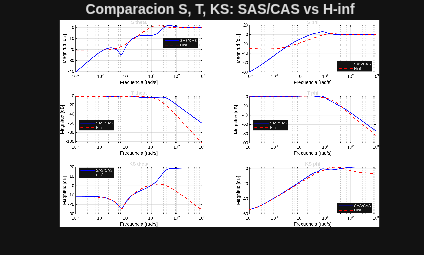

if exist(fullfile(figures_dir, 'comparacion_sensibilidades.png'), 'file')
    imshow(fullfile(figures_dir, 'comparacion_sensibilidades.png'));
    title('Comparacion S, T, KS: SAS/CAS vs H-inf');
end

## 9. Simulacion y resultados

La simulacion se realiza sobre `linmodel` acoplado (13 estados) con:

- Saturacion de actuadores a $\pm 30$ deg

- Anti-windup para el integrador del PID

- Ruido de medicion y perturbacion sinusoidal a 6 Hz

- Integracion con `ode45` (RelTol $10^{-6}$, AbsTol $10^{-8}$)

**Objetivo de los escenarios:**

- `theta_10` y `phi_10`: respuesta nominal de cada eje por separado.

- `theta_minus_10` y `phi_minus_10`: simetria ante referencias negativas.

- `theta_phi_10` y `theta_phi_30`: acoplamiento cuando pitch y roll se piden al mismo tiempo.

- `theta_30`, `phi_30`, `theta_40` y `phi_40`: cercania al limite de referencia y de actuador.

- `noise_disturbance`: robustez frente a ruido de medicion y perturbacion sinusoidal a 6 Hz.

**Estados internos del controlador:**

En el caso SAS/CAS, `ctrl.nx = 3` porque se simulan tres estados internos: el integrador de theta, el integrador de phi y el estado del yaw damper.

En el caso H-inf, el controlador es dinamico. Por eso se usa:

El ultimo `+1` corresponde al yaw damper. Asi el vector de estado total de la simulacion es `[x_planta; x_controlador]`.

**Funcion** `simulate_case`**:**

`simulate_case` ejecuta un escenario completo. Primero crea la grilla de tiempo, luego genera ruido si el escenario lo activa, arma el estado inicial de planta y controlador, integra con `ode45` y finalmente reconstruye referencias, salidas, comandos crudos, comandos saturados y metricas de RMS/error/saturacion.

**Respuestas seleccionadas:**

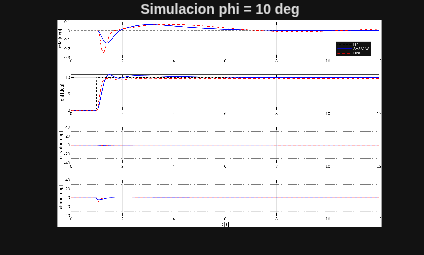

if exist(fullfile(figures_dir, 'sim_phi_10.png'), 'file')
    imshow(fullfile(figures_dir, 'sim_phi_10.png'));
    title('Simulacion phi = 10 deg');
end

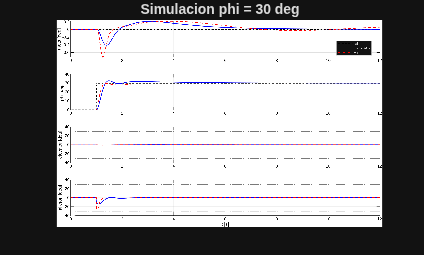

if exist(fullfile(figures_dir, 'sim_phi_30.png'), 'file')
    imshow(fullfile(figures_dir, 'sim_phi_30.png'));
    title('Simulacion phi = 30 deg');
end

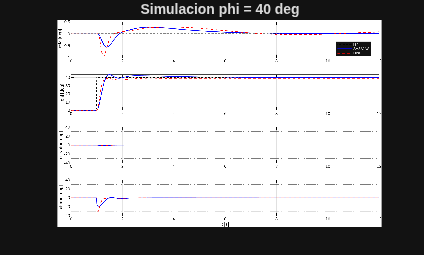

if exist(fullfile(figures_dir, 'sim_phi_40.png'), 'file')
    imshow(fullfile(figures_dir, 'sim_phi_40.png'));
    title('Simulacion phi = 40 deg');
end

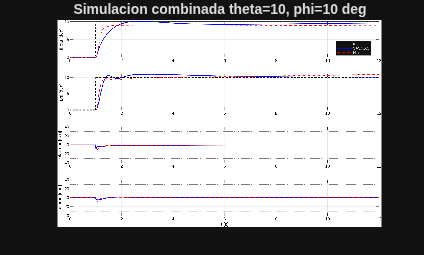

if exist(fullfile(figures_dir, 'sim_theta_phi_10.png'), 'file')
    imshow(fullfile(figures_dir, 'sim_theta_phi_10.png'));
    title('Simulacion combinada theta=10, phi=10 deg');
end

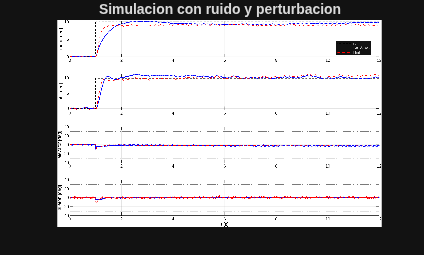

if exist(fullfile(figures_dir, 'sim_noise_disturbance.png'), 'file')
    imshow(fullfile(figures_dir, 'sim_noise_disturbance.png'));
    title('Simulacion con ruido y perturbacion');
end

**Comparaciones de RMS y saturacion:**

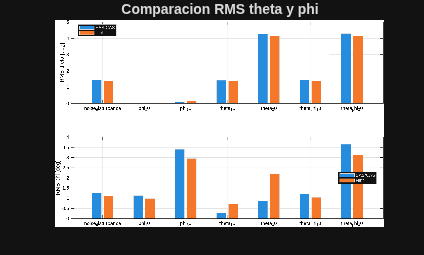

if exist(fullfile(figures_dir, 'comparacion_temporal_final.png'), 'file')
    imshow(fullfile(figures_dir, 'comparacion_temporal_final.png'));
    title('Comparacion RMS theta y phi');
end

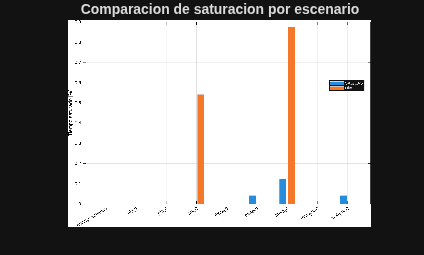

if exist(fullfile(figures_dir, 'comparacion_saturacion_final.png'), 'file')
    imshow(fullfile(figures_dir, 'comparacion_saturacion_final.png'));
    title('Comparacion de saturacion por escenario');
end

## 10. Gamma H-inf

La comparacion de gamma resume que el problema H-inf sigue siendo factible, pero ahora con pesos de control mas estrictos. El aumento de gamma frente a la version anterior es esperable: se le esta pidiendo al controlador que respete mejor el actuador.

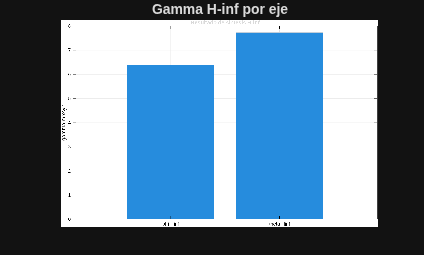

if exist(fullfile(figures_dir, 'comparacion_gamma_hinf.png'), 'file')
    imshow(fullfile(figures_dir, 'comparacion_gamma_hinf.png'));
    title('Gamma H-inf por eje');
end

## 11. Discusion y conclusiones

**Fortalezas SAS/CAS:**

- Simple de implementar y sintonizar

- Poco esfuerzo de actuador (KS bajo para phi)

- Tracking directo, intuitivo

**Fortalezas H-inf:**

- Diseno explicito con compromiso entre tracking, ruido y control

- $T$ baja en alta frecuencia (rechazo de ruido)

- Garantias formales de robustez via $\gamma$

**Limitaciones y compromiso final de H-inf:**

- Al subir $W_2$, H-inf deja de saturar en los escenarios de 30 deg

- El precio es un seguimiento mas lento que la version H-inf anterior

- Para 40 deg puede aparecer saturacion pequena, porque esta referencia esta por fuera del limite exigido para el actuador

**Estado de phi H-inf:**

- Saturacion phi_30: **0%**

- Saturacion theta_phi_30: **0%**

**Extension natural:**

- H-inf MIMO para manejar acoplamiento theta-phi

- Integracion explicita en el controlador robusto

## 12. Referencias

- Enunciado del Taller 1 — Teoria de Control Digital

- Notas de clase: Sofrony_c.pdf

- Documentacion MATLAB: `mixsyn`, `makeweight`, `augw`, `hinfsyn`

- Skogestad & Postlethwaite — *Multivariable Feedback Control*, Cap. 2, 9